# Gaussian Process Generation via Kernels

## Generating a GP

##  Linear kernel

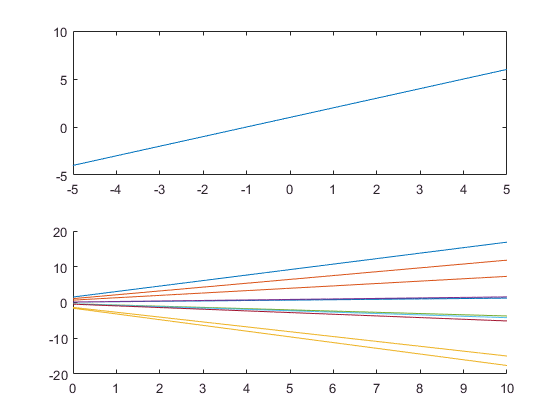

 
t=-5:0.01:5; % just for ploting the kernel
a = 0;
b = 1;
c = -1;
Lin = @(x1,x2) a^2 +b^2*(x1-c)*(x2-c);

figure
subplot(2,1,1)
plot(t,Lin(0,t))
subplot(2,1,2)
GP_example(Lin,10)

## RBF kernel (Squared Exponential Kernel)

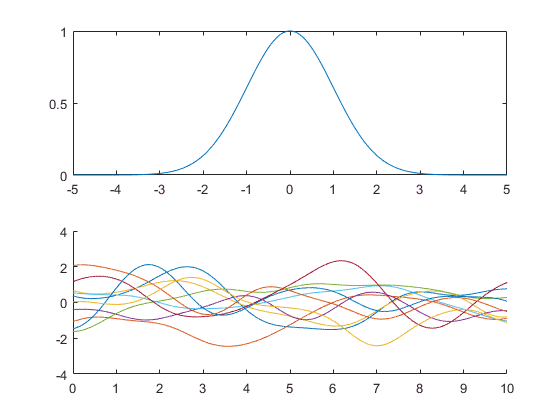


sig=1;
RBF=@(x1,x2)exp(-(x1-x2).^2/(2*sig^2));
figure
subplot(2,1,1)
plot(t,RBF(0,t))
subplot(2,1,2)
GP_example(RBF,10)

## Rational Quadratic Kernel

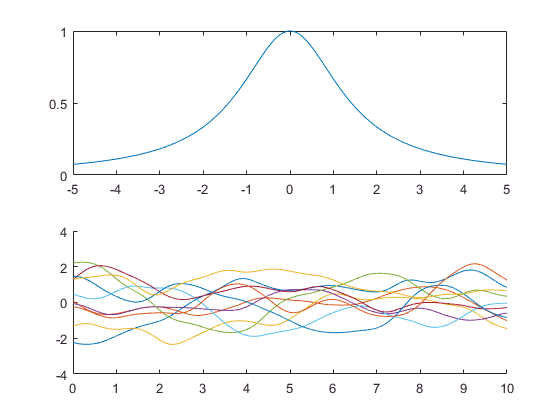


sig=1;
l = 1;
a = 1;
RQ=@(x1,x2)sig^2*(1+(x1-x2).^2/(2*a*l^2)).^(-a);
figure
subplot(2,1,1)
plot(t,RQ(0,t))
subplot(2,1,2)
GP_example(RQ,10)

## Periodic Kernel

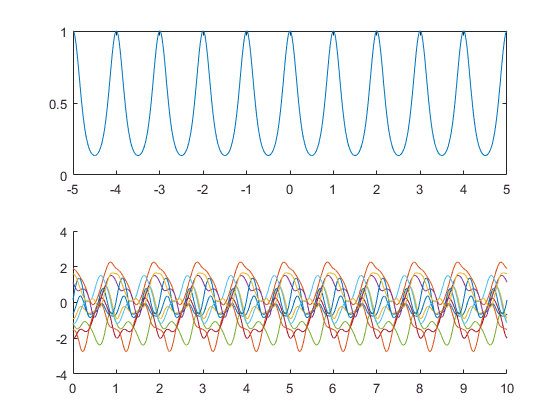

sig=1;
l = 1;
p = 1;
Per=@(x1,x2)sig^2*exp(-(2*sin(pi*abs(x1-x2)/p).^2)/l^2);
figure
subplot(2,1,1)
plot(t,Per(0,t))
subplot(2,1,2)
GP_example(Per,10)

## Locally Periodic Kernel

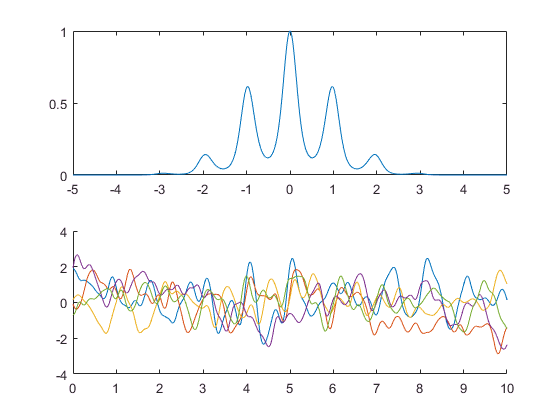

% let SE kernel times period kernel
sig = 1;
p = 1;
l = 1;

LP = @(x1,x2) sig^2*exp(-(2*sin(pi*abs(x1-x2)/p).^2)/l^2).*exp(-(x1-x2).^2/(2*l^2));

figure
subplot(2,1,1)
plot(t,LP(0,t))
subplot(2,1,2)
GP_example(LP,5)

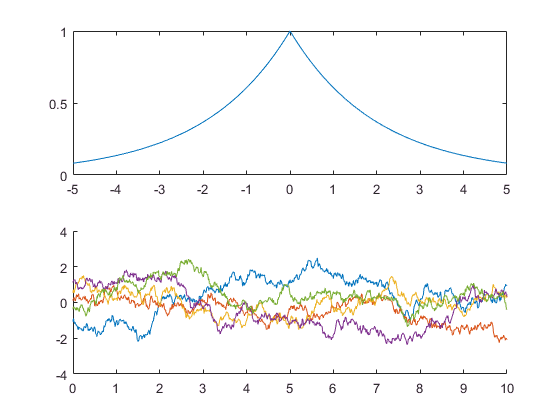

%% 
alpha=0.5;
Abel=@(x1,x2)exp(-alpha*abs(x1-x2));
figure
subplot(2,1,1)
plot(t,Abel(0,t))
subplot(2,1,2)
GP_example(Abel,5)

## combining kernel

## linear times periodic

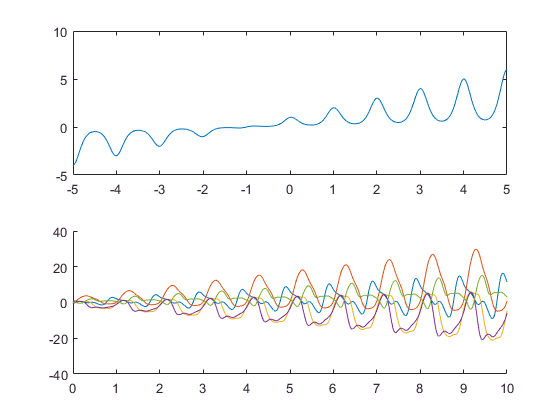

a = 0;
b = 1;
c = -1;
l = 1;

LinP = @(x1,x2) (a^2 +b^2*(x1-c)*(x2-c)).*exp(-(2*sin(pi*abs(x1-x2)/p).^2)/l^2);

figure
subplot(2,1,1)
plot(t,LinP(0,t))
subplot(2,1,2)
GP_example(LinP,5)

## adding kernels (from book of Bishop)

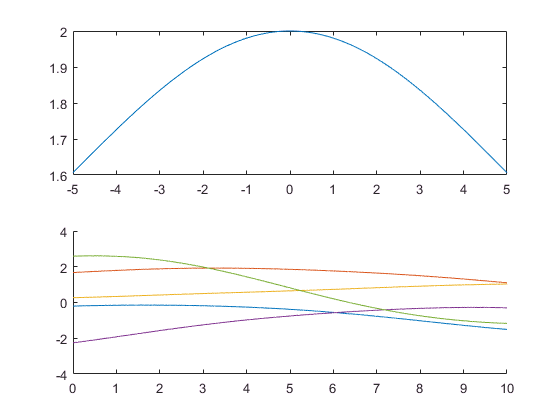

theta_0 = 1;
theta_1 = 0.04;
theta_2 = 1;
theta_3 = 0;


Combined = @(x1,x2) theta_0*exp(-theta_1*(x1-x2).^2/2)+theta_2 + theta_3*x1*x2;

figure
subplot(2,1,1)
plot(t,Combined(0,t))
subplot(2,1,2)
GP_example(Combined,5)

For different Positive-definite kernels, visit [Wiki page of Positive-definite kernel.](https://en.wikipedia.org/wiki/Positive-definite_kernel#Examples_of_p.d._kernels)

For details of how to choose the covarance function for gaussian process, read [The Kernel Cookbook](http://www.cs.toronto.edu/~duvenaud/cookbook/).